# Actividad 2.1 (Parametrización)

Ana Itzel Hernández García A0173756

%Limpieza de pantalla
clear all
close all
clc

**Implementación d**el código requerido para generar la parametrización de las siguientes trayectorias en un plano 2D.

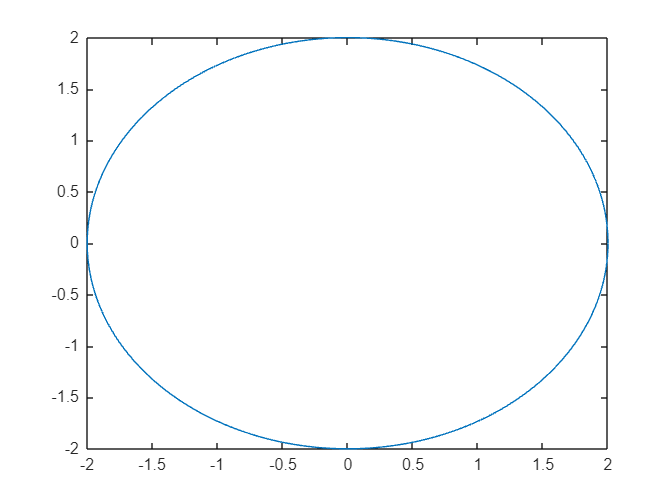

%Ejemplo 1 
%Se define el parpametro "t" de parametrizacipon sobre el cual se realizará
%la proyección de la trayectoria
t1 = [0:0.02:2*pi];

%Se definen las funciones en 2D
x1 = 2*cos(t1);
y1 = 2*sin(t1);

plot(x1,y1)

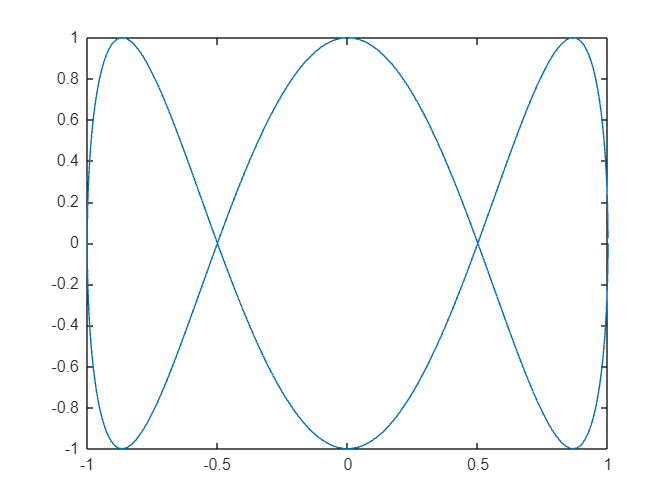


%Ejemplo 2 
%Se define el parpametro "t" de parametrizacipon sobre el cual se realizará
%la proyección de la trayectoria
t2 = [-2*pi:0.05:2*pi];

%Se definen las funciones en 2D
x2 = -cos(0.5*t2);
y2 = sin(1.5*t2);

plot(x2,y2)

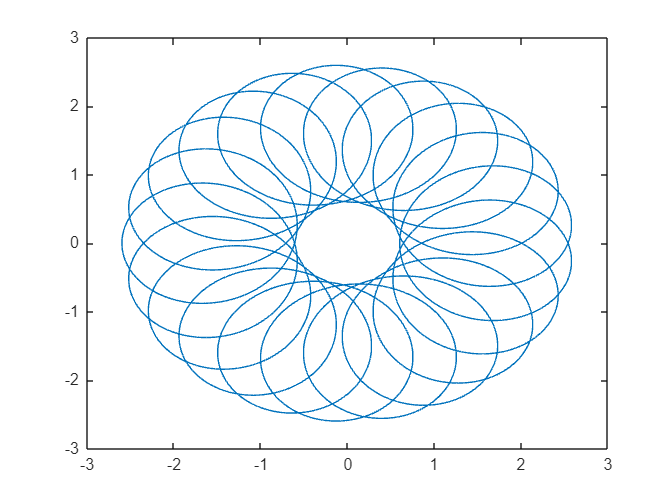


%Ejemplo 3 
%Se define el parpametro "t" de parametrizacipon sobre el cual se realizará
%la proyección de la trayectoria
t3 = [-10*pi:0.001:10*pi];

%Se definen las funciones en 2D
x3 = 1.6*cos(0.1*t3)- cos(2*t3);
y3 = 1.6*sin(0.1*t3) + sin(2*t3);

plot(x3,y3)

**Obtener** las siguientes trayectorias definidas a partir de curvas paramétricas

ins = ['a', 'b', 'c', 'd', 'e', 'f', 'g', 'h', 'i', 'j'];

Definición de los vectores los valores

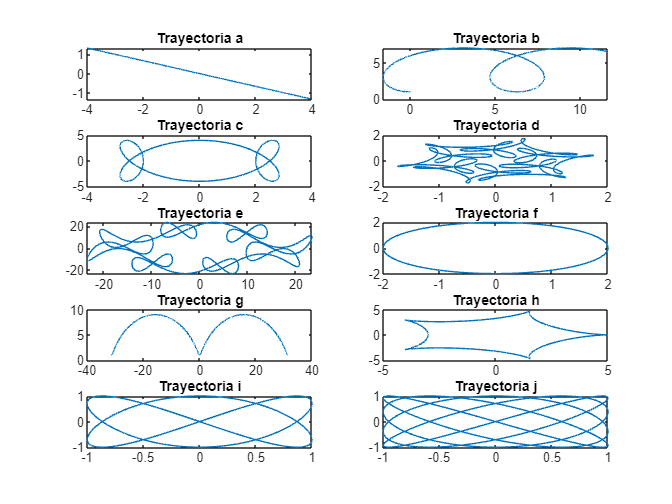

syms t
%Vector de los valores de x
x_vec=[2*t  ,t-3*sin(t)  ,3*cos(t)-cos(3*t)  ,cos(t)+1/2*cos(7*t)+1/3*sin(17*t)  ,17*cos(t)+7*cos(17+7*t)  ,2*cos(t)  ,5*t-4*sin(t)  ,4*cos(t)+cos(4*t)  ,sin(2*t)  ,sin(4*t)];
%Vector de los valores de y
y_vec=[(t-3*t)/3  ,4-3*cos(t)  ,4*sin(3*t)  , sin(t)+1/2*sin(7*t)+1/3*cos(17*t)  , 17*sin(t)-7*sin(17*t)  ,2*sin(t)  ,5-4*cos(t)  ,4*sin(t)-sin(4*t)  ,sin(3*t)  ,sin(5*t)];
%Vector de los valores de [ti:tf]
ti_vec=[-2  ,0  ,0  ,0  ,0  ,0  ,-2*pi  ,0  ,0  ,0];
tf_vec=[2  ,10  ,2*pi  ,2*pi  ,2*pi  ,14*pi  ,2*pi  ,2*pi  ,2*pi  ,2*pi];

index_order = reshape(1:10, [2,5])';

figure
hold on
for i = 1:10
    x = x_vec(i);
    y = y_vec(i);
    ti = ti_vec(i);
    tf = tf_vec(i);
 

    t_f = [ti:0.001:tf];
    xf = double((subs(x,t,t_f)));
    yf = double((subs(y,t,t_f)));

    subplot(5,2,i)
    plot(xf,yf)
    title(['Trayectoria ', ins(i)])
end 
hold off